## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6S_Drive = [50 35 20 35]*NS_L6/1e3 * StimulusFac;
L6C_Drive = [50 35 20 35]*NC_L6/1e3 * StimulusFac;
L6I_Drive = [50 35 20 35]*NI_L6/1e3 * StimulusFac;

rE_L6_Drive = [L6S_Drive(OD_S),L6C_Drive(OD_C)]';
rI_L6_Drive = L6I_Drive(OD_I)';


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
          'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
        FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 9.5693

FrECNow = 26.8716

FrINow = 57.0864

Elapsed time is 2.379091 seconds.


SampleInd = 3

FrESNow = 9.3202

FrECNow = 44.6642

FrINow = 70.2671

Elapsed time is 4.171241 seconds.


SampleInd = 4

FrESNow = 8.2195

FrECNow = 29.0864

FrINow = 59.6740

Elapsed time is 6.383234 seconds.


SampleInd = 5

FrESNow = 8.8296

FrECNow = 40.6667

FrINow = 68.4357

Elapsed time is 8.025281 seconds.


SampleInd = 6

FrESNow = 8.3226

FrECNow = 35.9753

FrINow = 64.8329

Elapsed time is 10.313947 seconds.


SampleInd = 7

FrESNow = 8.4016

FrECNow = 37.5704

FrINow = 65.9914

Elapsed time is 11.944601 seconds.


SampleInd = 8

FrESNow = 8.2864

FrECNow = 34.7630

FrINow = 64.2016

Elapsed time is 14.235791 seconds.


SampleInd = 9

FrESNow = 8.8395

FrECNow = 46.8272

FrINow = 73.6478

Elapsed time is 15.969309 seconds.


SampleInd = 10

FrESNow = 7.3756

FrECNow = 30.7679

FrINow = 60.4139

Elapsed time is 18.186196 seconds.


SampleInd = 11

FrESNow = 8.4840

FrECNow = 40.6420

FrINow = 68.3270

Elapsed time is 19.841204 seconds.


SampleInd = 12

FrESNow = 8.1416

FrECNow = 39.5802

FrINow = 67.5523

Elapsed time is 22.216577 seconds.


SampleInd = 13

FrESNow = 8.0604

FrECNow = 32.5185

FrINow = 61.9702

Elapsed time is 23.742202 seconds.


SampleInd = 14

FrESNow = 8.7353

FrECNow = 42.8370

FrINow = 69.9919

Elapsed time is 26.176849 seconds.


SampleInd = 15

FrESNow = 7.9177

FrECNow = 36.3605

FrINow = 64.8052

Elapsed time is 27.776674 seconds.


SampleInd = 16

FrESNow = 8.3171

FrECNow = 37.9630

FrINow = 66.7037

Elapsed time is 30.114875 seconds.


SampleInd = 17

FrESNow = 8.1800

FrECNow = 39.9136

FrINow = 67.3997

Elapsed time is 31.707639 seconds.


SampleInd = 18

FrESNow = 8.2776

FrECNow = 34.9136

FrINow = 64.4283

Elapsed time is 33.975446 seconds.


SampleInd = 19

FrESNow = 8.1866

FrECNow = 41.3383

FrINow = 68.7987

Elapsed time is 35.575150 seconds.


SampleInd = 20

FrESNow = 8.0516

FrECNow = 33.7210

FrINow = 63.1056

Elapsed time is 37.807088 seconds.


SampleInd = 21

FrESNow = 8.8077

FrECNow = 50.4938

FrINow = 75.8747

Elapsed time is 39.547594 seconds.


Elapsed time is 39.548379 seconds.


SampleInd = 22

FrESNow = 7.3646

FrECNow = 27.6444

FrINow = 58.8022

Elapsed time is 2.123876 seconds.


SampleInd = 23

FrESNow = 8.7715

FrECNow = 43.1457

FrINow = 70.5631

Elapsed time is 3.835862 seconds.


SampleInd = 24

FrESNow = 8.2765

FrECNow = 38.7556

FrINow = 67.1870

Elapsed time is 6.148381 seconds.


SampleInd = 25

FrESNow = 8.0143

FrECNow = 35.9630

FrINow = 64.9277

Elapsed time is 7.716689 seconds.


SampleInd = 26

FrESNow = 8.3018

FrECNow = 37.0593

FrINow = 66.0793

Elapsed time is 9.990729 seconds.


SampleInd = 27

FrESNow = 8.5849

FrECNow = 45.6370

FrINow = 72.7159

Elapsed time is 11.694702 seconds.


SampleInd = 28

FrESNow = 7.6027

FrECNow = 30.1630

FrINow = 60.4185

Elapsed time is 13.818478 seconds.


SampleInd = 29

FrESNow = 8.9207

FrECNow = 48.5383

FrINow = 74.3485

Elapsed time is 15.573695 seconds.


SampleInd = 30

FrESNow = 7.4787

FrECNow = 27.6420

FrINow = 58.6126

Elapsed time is 17.653926 seconds.


SampleInd = 31

FrESNow = 8.9240

FrECNow = 52.9753

FrINow = 77.9096

Elapsed time is 19.421558 seconds.


SampleInd = 32

FrESNow = 7.3416

FrECNow = 28.2790

FrINow = 58.9918

Elapsed time is 21.596607 seconds.


SampleInd = 33

FrESNow = 8.5454

FrECNow = 43.0938

FrINow = 70.4382

Elapsed time is 23.233305 seconds.


SampleInd = 34

FrESNow = 8.1130

FrECNow = 35.9506

FrINow = 64.6942

Elapsed time is 25.510568 seconds.


SampleInd = 35

FrESNow = 8.3369

FrECNow = 34.6519

FrINow = 64.0120

Elapsed time is 27.044770 seconds.


SampleInd = 36

FrESNow = 8.2952

FrECNow = 45.3457

FrINow = 71.5828

Elapsed time is 29.392111 seconds.


SampleInd = 37

FrESNow = 7.9605

FrECNow = 34.1877

FrINow = 63.6767

Elapsed time is 30.882909 seconds.


SampleInd = 38

FrESNow = 8.3512

FrECNow = 41.3753

FrINow = 69.1155

Elapsed time is 33.147034 seconds.


SampleInd = 39

FrESNow = 7.9737

FrECNow = 30.0370

FrINow = 60.5319

Elapsed time is 34.636212 seconds.


SampleInd = 40

FrESNow = 8.7484

FrECNow = 44.5432

FrINow = 71.2314

Elapsed time is 37.030677 seconds.


SampleInd = 41

FrESNow = 7.9868

FrECNow = 37.4395

FrINow = 66.2042

Elapsed time is 38.641587 seconds.


Elapsed time is 38.642314 seconds.


SampleInd = 42

FrESNow = 8.2107

FrECNow = 38.7605

FrINow = 66.9187

Elapsed time is 2.306487 seconds.


SampleInd = 43

FrESNow = 8.1888

FrECNow = 39.1160

FrINow = 66.8586

Elapsed time is 3.965155 seconds.


SampleInd = 44

FrESNow = 8.2414

FrECNow = 36.8568

FrINow = 65.8273

Elapsed time is 6.191470 seconds.


SampleInd = 45

FrESNow = 8.2996

FrECNow = 37.3284

FrINow = 66.0747

Elapsed time is 7.796663 seconds.


SampleInd = 46

FrESNow = 8.5739

FrECNow = 41.3580

FrINow = 69.1618

Elapsed time is 10.104499 seconds.


SampleInd = 47

FrESNow = 8.1317

FrECNow = 35.2815

FrINow = 64.6687

Elapsed time is 11.704778 seconds.


SampleInd = 48

FrESNow = 8.2392

FrECNow = 36.7136

FrINow = 65.6122

Elapsed time is 13.924761 seconds.


SampleInd = 49

FrESNow = 8.4763

FrECNow = 40.1309

FrINow = 68.5143

Elapsed time is 15.521570 seconds.


SampleInd = 50

FrESNow = 8.2085

FrECNow = 35.1654

FrINow = 64.5739

Elapsed time is 17.726515 seconds.


SampleInd = 51

FrESNow = 8.0417

FrECNow = 37.1531

FrINow = 65.6723

Elapsed time is 19.267401 seconds.


SampleInd = 52

FrESNow = 8.9306

FrECNow = 43.6469

FrINow = 71.1527

Elapsed time is 21.622262 seconds.


SampleInd = 53

FrESNow = 7.8562

FrECNow = 38.5210

FrINow = 66.6435

Elapsed time is 23.236759 seconds.


SampleInd = 54

FrESNow = 8.2458

FrECNow = 35.8889

FrINow = 65.2815

Elapsed time is 25.490368 seconds.


SampleInd = 55

FrESNow = 8.1262

FrECNow = 33.4395

FrINow = 62.7448

Elapsed time is 27.013161 seconds.


SampleInd = 56

FrESNow = 8.6639

FrECNow = 46.7259

FrINow = 72.7969

Elapsed time is 29.380098 seconds.


SampleInd = 57

FrESNow = 8.0790

FrECNow = 35.4765

FrINow = 64.7636

Elapsed time is 30.915639 seconds.


SampleInd = 58

FrESNow = 8.3929

FrECNow = 39.7358

FrINow = 68.2484

Elapsed time is 33.252206 seconds.


SampleInd = 59

FrESNow = 8.2337

FrECNow = 35.8222

FrINow = 65.1613

Elapsed time is 34.885881 seconds.


SampleInd = 60

FrESNow = 8.4401

FrECNow = 37.9136

FrINow = 66.5927

Elapsed time is 37.137436 seconds.


SampleInd = 61

FrESNow = 8.5103

FrECNow = 41.0346

FrINow = 68.8334

Elapsed time is 38.745653 seconds.


Elapsed time is 38.746371 seconds.


SampleInd = 62

FrESNow = 7.9770

FrECNow = 36.3852

FrINow = 65.0896

Elapsed time is 2.215423 seconds.


SampleInd = 63

FrESNow = 8.2787

FrECNow = 41.5062

FrINow = 69.1086

Elapsed time is 3.852331 seconds.


SampleInd = 64

FrESNow = 8.2469

FrECNow = 33.9012

FrINow = 63.5149

Elapsed time is 6.056959 seconds.


SampleInd = 65

FrESNow = 8.7353

FrECNow = 45.8346

FrINow = 72.8246

Elapsed time is 7.729388 seconds.


SampleInd = 66

FrESNow = 7.8255

FrECNow = 30.6543

FrINow = 61.4453

Elapsed time is 9.860672 seconds.


SampleInd = 67

FrESNow = 9.1523

FrECNow = 46.3111

FrINow = 73.3449

Elapsed time is 11.576852 seconds.


SampleInd = 68

FrESNow = 7.4645

FrECNow = 30.6074

FrINow = 60.6243

Elapsed time is 13.766654 seconds.


SampleInd = 69

FrESNow = 8.6584

FrECNow = 39.6494

FrINow = 67.8344

Elapsed time is 15.413956 seconds.


SampleInd = 70

FrESNow = 8.2403

FrECNow = 37.8123

FrINow = 66.1787

Elapsed time is 17.688508 seconds.


SampleInd = 71

FrESNow = 8.2228

FrECNow = 35.1185

FrINow = 64.3936

Elapsed time is 19.212067 seconds.


SampleInd = 72

FrESNow = 8.2447

FrECNow = 37.5506

FrINow = 66.2967

Elapsed time is 21.418543 seconds.


SampleInd = 73

FrESNow = 8.5487

FrECNow = 40.5383

FrINow = 68.3455

Elapsed time is 22.988186 seconds.


SampleInd = 74

FrESNow = 8.3095

FrECNow = 37.0173

FrINow = 66.1071

Elapsed time is 25.181057 seconds.


SampleInd = 75

FrESNow = 8.2403

FrECNow = 36.0593

FrINow = 65.0827

Elapsed time is 26.756427 seconds.


SampleInd = 76

FrESNow = 8.5147

FrECNow = 43.3926

FrINow = 71.0302

Elapsed time is 29.059270 seconds.


SampleInd = 77

FrESNow = 7.7937

FrECNow = 34.3728

FrINow = 63.6004

Elapsed time is 30.551549 seconds.


SampleInd = 78

FrESNow = 8.4137

FrECNow = 38.2395

FrINow = 66.6204

Elapsed time is 32.747212 seconds.


SampleInd = 79

FrESNow = 8.2700

FrECNow = 40.4469

FrINow = 67.8529

Elapsed time is 34.341360 seconds.


SampleInd = 80

FrESNow = 7.9122

FrECNow = 35.1259

FrINow = 63.9450

Elapsed time is 36.513070 seconds.


SampleInd = 81

FrESNow = 8.7813

FrECNow = 44.2938

FrINow = 71.6175

Elapsed time is 38.154975 seconds.


Elapsed time is 38.155700 seconds.


SampleInd = 82

FrESNow = 8.0878

FrECNow = 32.1605

FrINow = 62.4974

Elapsed time is 2.199829 seconds.


SampleInd = 83

FrESNow = 8.3084

FrECNow = 39.7284

FrINow = 67.7257

Elapsed time is 3.901372 seconds.


SampleInd = 84

FrESNow = 8.4291

FrECNow = 42.6543

FrINow = 70.3735

Elapsed time is 6.198244 seconds.


SampleInd = 85

FrESNow = 7.8705

FrECNow = 31.7062

FrINow = 61.9124

Elapsed time is 7.745989 seconds.


SampleInd = 86

FrESNow = 8.7166

FrECNow = 43.1728

FrINow = 70.4197

Elapsed time is 10.110416 seconds.


SampleInd = 87

FrESNow = 7.6675

FrECNow = 32.2469

FrINow = 61.7782

Elapsed time is 11.645736 seconds.


SampleInd = 88

FrESNow = 8.6420

FrECNow = 45.5136

FrINow = 72.1841

Elapsed time is 14.000692 seconds.


SampleInd = 89

FrESNow = 7.9144

FrECNow = 31.3975

FrINow = 61.7574

Elapsed time is 15.481539 seconds.


SampleInd = 90

FrESNow = 8.5948

FrECNow = 45.6395

FrINow = 72.4361

Elapsed time is 17.827775 seconds.


SampleInd = 91

FrESNow = 8.1975

FrECNow = 32.9531

FrINow = 63.1264

Elapsed time is 19.328187 seconds.


SampleInd = 92

FrESNow = 8.4170

FrECNow = 40.7975

FrINow = 68.1374

Elapsed time is 21.601612 seconds.


SampleInd = 93

FrESNow = 8.5070

FrECNow = 39.8938

FrINow = 68.3686

Elapsed time is 23.205818 seconds.


SampleInd = 94

FrESNow = 8.0669

FrECNow = 40.3259

FrINow = 68.0009

Elapsed time is 25.485194 seconds.


SampleInd = 95

FrESNow = 7.9978

FrECNow = 28.5407

FrINow = 59.8636

Elapsed time is 26.930071 seconds.


SampleInd = 96

FrESNow = 8.6233

FrECNow = 47.1802

FrINow = 73.2108

Elapsed time is 29.365007 seconds.


SampleInd = 97

FrESNow = 8.2392

FrECNow = 36.6000

FrINow = 65.9082

Elapsed time is 30.989153 seconds.


SampleInd = 98

FrESNow = 7.9934

FrECNow = 37.8346

FrINow = 66.2921

Elapsed time is 33.245932 seconds.


SampleInd = 99

FrESNow = 8.3084

FrECNow = 35.0963

FrINow = 64.8283

Elapsed time is 34.772081 seconds.


SampleInd = 100

FrESNow = 8.3929

FrECNow = 43.4099

FrINow = 70.6879

Elapsed time is 37.084347 seconds.


SampleInd = 101

FrESNow = 8.0132

FrECNow = 34.0025

FrINow = 63.4871

Elapsed time is 38.584630 seconds.


Elapsed time is 38.585431 seconds.


SampleInd = 102

FrESNow = 8.4148

FrECNow = 43.4988

FrINow = 71.0024

Elapsed time is 2.406347 seconds.


SampleInd = 103

FrESNow = 7.9868

FrECNow = 39.0395

FrINow = 67.4020

Elapsed time is 4.014051 seconds.


SampleInd = 104

FrESNow = 8.2085

FrECNow = 36.1062

FrINow = 65.3717

Elapsed time is 6.229910 seconds.


SampleInd = 105

FrESNow = 8.1405

FrECNow = 33.0543

FrINow = 62.7263

Elapsed time is 7.768948 seconds.


SampleInd = 106

FrESNow = 8.6123

FrECNow = 44.1506

FrINow = 71.2915

Elapsed time is 10.194207 seconds.


SampleInd = 107

FrESNow = 7.9616

FrECNow = 35.2988

FrINow = 63.9403

Elapsed time is 11.788388 seconds.


SampleInd = 108

FrESNow = 8.5454

FrECNow = 40.7037

FrINow = 69.1386

Elapsed time is 14.159827 seconds.


SampleInd = 109

FrESNow = 8.0483

FrECNow = 38.2444

FrINow = 66.8262

Elapsed time is 15.727958 seconds.


SampleInd = 110

FrESNow = 8.2765

FrECNow = 34.7605

FrINow = 64.1068

Elapsed time is 17.986433 seconds.


SampleInd = 111

FrESNow = 8.3139

FrECNow = 36.2790

FrINow = 64.9647

Elapsed time is 19.548014 seconds.


SampleInd = 112

FrESNow = 8.4148

FrECNow = 50.1630

FrINow = 75.4862

Elapsed time is 22.068774 seconds.


SampleInd = 113

FrESNow = 7.4667

FrECNow = 26.1333

FrINow = 57.8772

Elapsed time is 23.495455 seconds.


SampleInd = 114

FrESNow = 8.8735

FrECNow = 46.5407

FrINow = 73.0928

Elapsed time is 25.864985 seconds.


SampleInd = 115

FrESNow = 7.6269

FrECNow = 29.9160

FrINow = 60.1665

Elapsed time is 27.333851 seconds.


SampleInd = 116

FrESNow = 8.9503

FrECNow = 46.4963

FrINow = 72.9795

Elapsed time is 29.720266 seconds.


SampleInd = 117

FrESNow = 8.0274

FrECNow = 31.7926

FrINow = 62.1945

Elapsed time is 31.215399 seconds.


SampleInd = 118

FrESNow = 8.5717

FrECNow = 44.8395

FrINow = 71.5019

Elapsed time is 33.569043 seconds.


SampleInd = 119

FrESNow = 7.5479

FrECNow = 28.4519

FrINow = 59.0172

Elapsed time is 34.961259 seconds.


SampleInd = 120

FrESNow = 8.5235

FrECNow = 38.7185

FrINow = 66.9187

Elapsed time is 37.256340 seconds.


SampleInd = 121

FrESNow = 8.6519

FrECNow = 45.9358

FrINow = 72.5194

Elapsed time is 38.947891 seconds.


Elapsed time is 38.948601 seconds.


SampleInd = 122

FrESNow = 7.8519

FrECNow = 29.5951

FrINow = 60.4463

Elapsed time is 2.211456 seconds.


SampleInd = 123

FrESNow = 8.7298

FrECNow = 41.8000

FrINow = 69.5364

Elapsed time is 3.886935 seconds.


SampleInd = 124

FrESNow = 8.2722

FrECNow = 37.3284

FrINow = 66.2620

Elapsed time is 6.119965 seconds.


SampleInd = 125

FrESNow = 8.0219

FrECNow = 36.4074

FrINow = 64.8884

Elapsed time is 7.647096 seconds.


SampleInd = 126

FrESNow = 8.6222

FrECNow = 42.3481

FrINow = 69.8717

Elapsed time is 9.965262 seconds.


SampleInd = 127

FrESNow = 8.1591

FrECNow = 39.5259

FrINow = 67.9847

Elapsed time is 11.544891 seconds.


SampleInd = 128

FrESNow = 8.2085

FrECNow = 36.3358

FrINow = 65.5243

Elapsed time is 13.751636 seconds.


SampleInd = 129

FrESNow = 8.1975

FrECNow = 37.1802

FrINow = 65.7047

Elapsed time is 15.291356 seconds.


SampleInd = 130

FrESNow = 8.6376

FrECNow = 39.6395

FrINow = 68.3108

Elapsed time is 17.546606 seconds.


SampleInd = 131

FrESNow = 8.1372

FrECNow = 38.6765

FrINow = 66.9881

Elapsed time is 19.215894 seconds.


SampleInd = 132

FrESNow = 8.2908

FrECNow = 33.2025

FrINow = 63.1587

Elapsed time is 21.357901 seconds.


SampleInd = 133

FrESNow = 9.2675

FrECNow = 57.6321

FrINow = 81.9285

Elapsed time is 23.182136 seconds.


SampleInd = 134

FrESNow = 6.8653

FrECNow = 20.4642

FrINow = 53.3079

Elapsed time is 25.184205 seconds.


SampleInd = 135

FrESNow = 8.9416

FrECNow = 46.7852

FrINow = 72.9657

Elapsed time is 26.877272 seconds.


SampleInd = 136

FrESNow = 7.8551

FrECNow = 34.3432

FrINow = 63.8571

Elapsed time is 29.068960 seconds.


SampleInd = 137

FrESNow = 8.3687

FrECNow = 38.2272

FrINow = 66.6135

Elapsed time is 30.634763 seconds.


SampleInd = 138

FrESNow = 8.5476

FrECNow = 48.2321

FrINow = 74.3115

Elapsed time is 33.007165 seconds.


SampleInd = 139

FrESNow = 7.6719

FrECNow = 29.1926

FrINow = 60.0555

Elapsed time is 34.436652 seconds.


SampleInd = 140

FrESNow = 8.5728

FrECNow = 41.0296

FrINow = 68.5420

Elapsed time is 36.694994 seconds.


SampleInd = 141

FrESNow = 8.3698

FrECNow = 39.7457

FrINow = 68.2299

Elapsed time is 38.390704 seconds.


Elapsed time is 38.391402 seconds.


SampleInd = 142

FrESNow = 8.1097

FrECNow = 35.3012

FrINow = 64.3820

Elapsed time is 2.220149 seconds.


SampleInd = 143

FrESNow = 8.1767

FrECNow = 38.2938

FrINow = 66.6667

Elapsed time is 3.827413 seconds.


SampleInd = 144

FrESNow = 8.6837

FrECNow = 41.6840

FrINow = 69.8578

Elapsed time is 6.210303 seconds.


SampleInd = 145

FrESNow = 7.7816

FrECNow = 35.6765

FrINow = 64.5786

Elapsed time is 7.810499 seconds.


SampleInd = 146

FrESNow = 8.7276

FrECNow = 42.2370

FrINow = 70.3966

Elapsed time is 10.136709 seconds.


SampleInd = 147

FrESNow = 7.7235

FrECNow = 32.4074

FrINow = 62.0442

Elapsed time is 11.605552 seconds.


SampleInd = 148

FrESNow = 8.5783

FrECNow = 43.7111

FrINow = 70.5446

Elapsed time is 13.905243 seconds.


SampleInd = 149

FrESNow = 8.0768

FrECNow = 35.7407

FrINow = 64.3681

Elapsed time is 15.419382 seconds.


SampleInd = 150

FrESNow = 8.4313

FrECNow = 38.0840

FrINow = 67.0135

Elapsed time is 17.663779 seconds.


SampleInd = 151

FrESNow = 8.0999

FrECNow = 39.5284

FrINow = 67.6841

Elapsed time is 19.328543 seconds.


SampleInd = 152

FrESNow = 8.0593

FrECNow = 37.9383

FrINow = 66.0955

Elapsed time is 21.550068 seconds.


SampleInd = 153

FrESNow = 8.1855

FrECNow = 36.7877

FrINow = 65.6585

Elapsed time is 23.107174 seconds.


SampleInd = 154

FrESNow = 8.3720

FrECNow = 41.1481

FrINow = 69.0808

Elapsed time is 25.427399 seconds.


SampleInd = 155

FrESNow = 8.1262

FrECNow = 35.4593

FrINow = 64.8006

Elapsed time is 27.023915 seconds.


SampleInd = 156

FrESNow = 8.4335

FrECNow = 37.2765

FrINow = 66.0747

Elapsed time is 29.325044 seconds.


SampleInd = 157

FrESNow = 8.5202

FrECNow = 45.1951

FrINow = 71.8280

Elapsed time is 31.032076 seconds.


SampleInd = 158

FrESNow = 7.7246

FrECNow = 30.0568

FrINow = 60.6544

Elapsed time is 33.194324 seconds.


SampleInd = 159

FrESNow = 8.6167

FrECNow = 40.1160

FrINow = 68.2252

Elapsed time is 34.796245 seconds.


SampleInd = 160

FrESNow = 8.2359

FrECNow = 41.5679

FrINow = 69.2843

Elapsed time is 37.147727 seconds.


SampleInd = 161

FrESNow = 8.1624

FrECNow = 37.3877

FrINow = 66.1071

Elapsed time is 38.762056 seconds.


Elapsed time is 38.762758 seconds.


SampleInd = 162

FrESNow = 8.3786

FrECNow = 44.1333

FrINow = 70.9978

Elapsed time is 2.374658 seconds.


SampleInd = 163

FrESNow = 7.9144

FrECNow = 32.1086

FrINow = 62.5113

Elapsed time is 3.883602 seconds.


SampleInd = 164

FrESNow = 8.3786

FrECNow = 39.9679

FrINow = 67.8437

Elapsed time is 6.167530 seconds.


SampleInd = 165

FrESNow = 8.1679

FrECNow = 37.8099

FrINow = 66.3984

Elapsed time is 7.738783 seconds.


SampleInd = 166

FrESNow = 8.3665

FrECNow = 41.3259

FrINow = 69.0739

Elapsed time is 10.009147 seconds.


SampleInd = 167

FrESNow = 8.0033

FrECNow = 34.5679

FrINow = 64.1415

Elapsed time is 11.532310 seconds.


SampleInd = 168

FrESNow = 8.6639

FrECNow = 42.9358

FrINow = 70.8937

Elapsed time is 13.855152 seconds.


SampleInd = 169

FrESNow = 7.8222

FrECNow = 32.8988

FrINow = 62.6338

Elapsed time is 15.340602 seconds.


SampleInd = 170

FrESNow = 8.5728

FrECNow = 37.8914

FrINow = 66.7083

Elapsed time is 17.572507 seconds.


SampleInd = 171

FrESNow = 8.4719

FrECNow = 40.5185

FrINow = 68.4056

Elapsed time is 19.146225 seconds.


SampleInd = 172

FrESNow = 8.2436

FrECNow = 39.4667

FrINow = 67.9593

Elapsed time is 21.421981 seconds.


SampleInd = 173

FrESNow = 8.1855

FrECNow = 40.9778

FrINow = 68.6553

Elapsed time is 23.010768 seconds.


SampleInd = 174

FrESNow = 8.3457

FrECNow = 38.1580

FrINow = 67.1523

Elapsed time is 25.247415 seconds.


SampleInd = 175

FrESNow = 7.9111

FrECNow = 36.5111

FrINow = 64.8121

Elapsed time is 26.789795 seconds.


SampleInd = 176

FrESNow = 8.4993

FrECNow = 39.2840

FrINow = 67.6055

Elapsed time is 29.039545 seconds.


SampleInd = 177

FrESNow = 8.4170

FrECNow = 42.9506

FrINow = 70.1353

Elapsed time is 30.658253 seconds.


SampleInd = 178

FrESNow = 7.9759

FrECNow = 33.7432

FrINow = 63.5657

Elapsed time is 32.839313 seconds.


SampleInd = 179

FrESNow = 8.3303

FrECNow = 39.3580

FrINow = 67.5014

Elapsed time is 34.424735 seconds.


SampleInd = 180

FrESNow = 8.3358

FrECNow = 37.3654

FrINow = 65.7972

Elapsed time is 36.682904 seconds.


SampleInd = 181

FrESNow = 8.2491

FrECNow = 42.7160

FrINow = 69.9873

Elapsed time is 38.313997 seconds.


Elapsed time is 38.314748 seconds.


SampleInd = 182

FrESNow = 7.9287

FrECNow = 32.7630

FrINow = 62.3055

Elapsed time is 2.161194 seconds.


SampleInd = 183

FrESNow = 8.6639

FrECNow = 45.4222

FrINow = 72.1286

Elapsed time is 3.924872 seconds.


SampleInd = 184

FrESNow = 7.7750

FrECNow = 31.5432

FrINow = 61.7898

Elapsed time is 6.100974 seconds.


SampleInd = 185

FrESNow = 8.6255

FrECNow = 36.9012

FrINow = 65.7301

Elapsed time is 7.708147 seconds.


SampleInd = 186

FrESNow = 8.4905

FrECNow = 39.8914

FrINow = 68.0194

Elapsed time is 10.050571 seconds.


SampleInd = 187

FrESNow = 8.5992

FrECNow = 41.7086

FrINow = 69.7607

Elapsed time is 11.790994 seconds.


SampleInd = 188

FrESNow = 7.7739

FrECNow = 38.4420

FrINow = 66.7661

Elapsed time is 14.002835 seconds.


SampleInd = 189

FrESNow = 8.1877

FrECNow = 31.4914

FrINow = 61.6742

Elapsed time is 15.469999 seconds.


SampleInd = 190

FrESNow = 8.5717

FrECNow = 42.8173

FrINow = 70.0705

Elapsed time is 17.768279 seconds.


SampleInd = 191

FrESNow = 7.9155

FrECNow = 33.9975

FrINow = 62.7633

Elapsed time is 19.292377 seconds.


SampleInd = 192

FrESNow = 8.7320

FrECNow = 44.3185

FrINow = 71.7910

Elapsed time is 21.606258 seconds.


SampleInd = 193

FrESNow = 7.7860

FrECNow = 33.7778

FrINow = 62.8651

Elapsed time is 23.089270 seconds.


SampleInd = 194

FrESNow = 8.6519

FrECNow = 41.7753

FrINow = 69.5132

Elapsed time is 25.373136 seconds.


SampleInd = 195

FrESNow = 7.9945

FrECNow = 39.0568

FrINow = 67.3118

Elapsed time is 26.957452 seconds.


SampleInd = 196

FrESNow = 8.0549

FrECNow = 33.0889

FrINow = 62.6986

Elapsed time is 29.093954 seconds.


SampleInd = 197

FrESNow = 8.5860

FrECNow = 47.2988

FrINow = 72.9448

Elapsed time is 30.767794 seconds.


SampleInd = 198

FrESNow = 7.8848

FrECNow = 30.2173

FrINow = 60.9065

Elapsed time is 32.929743 seconds.


SampleInd = 199

FrESNow = 8.5125

FrECNow = 44.7012

FrINow = 71.2244

Elapsed time is 34.674556 seconds.


SampleInd = 200

FrESNow = 7.8694

FrECNow = 32.6568

FrINow = 62.4535

Elapsed time is 36.876111 seconds.


SampleInd = 201

FrESNow = 8.5289

FrECNow = 42.9086

FrINow = 69.9850

Elapsed time is 38.511206 seconds.


Elapsed time is 38.511900 seconds.


save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

 read data, and get spike and mV

SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([SaveFolder text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

Check soome time dependency// cental hypercolum??

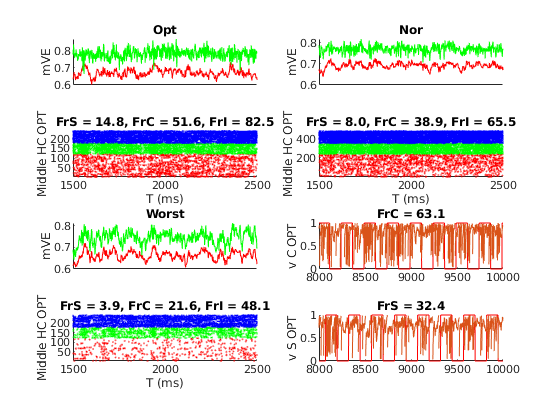

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1.25*n_S_HC & NnS.X<=1.75*n_S_HC;
MidRowS = NnS.Y>=1.25*n_S_HC & NnS.Y<=1.75*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1.25*n_C_HC & NnC.X<=1.75*n_C_HC;
MidRowC = NnC.Y>=1.25*n_C_HC & NnC.Y<=1.75*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

SOpt = find(OptE & ~EcplxInd);
scatterSOpt = find(ismember(SpE(:,1), SOpt));
[~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);

COpt = find(OptE & EcplxInd);
scatterCOpt = find(ismember(SpE(:,1), COpt));
[~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [1500 2500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');  
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');  
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');  
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);